# problem 4

clear; clc; close all;
format short g;
addpath(genpath(fullfile(pwd, 'scripts')));

## User choices

Kq_pick = 0.4;      % pitch damper
Kp_roll_pick = 0.2; % roll damper
Kv_pick = 0.15;     % proportional airspeed gain 
Ki_pick = 0.02;     % integral airspeed gain

## Trim and linearize the Euler plant

data = linearize_reduced_flight_dynamics_eul('CruiseSpeed', 70, 'DisplayReport', 'off');


trimSummary = table( ...
    data.trimPoint.inputs.front_collective_rpm, ...
    data.trimPoint.inputs.rear_collective_rpm, ...
    rad2deg(data.trimPoint.inputs.delta_e), ...
    rad2deg(data.trimPoint.eul(2)), ...
    norm(data.trimPoint.velocity), ...
    'VariableNames', {'front_collective_rpm','rear_collective_rpm','delta_e_deg','theta_deg','vinf_mps'})

trimSummary = 1×5 table
    front_collective_rpm    rear_collective_rpm    delta_e_deg    theta_deg    vinf_mps
    ____________________    ___________________    ___________    _________    ________

           1181.4                    0               -15.06        2.6325         70   


## Full model states and grouped inputs

I am ignoring position states and psi for the control design model.

fullStateNames = string(data.full.StateName(:));
fullInputNames = string(data.full.InputName([19 20 22 23 24]));

fullStateNames

fullStateNames = 12×1 string array
    "Euler Rot Kinematics/Integrator(1)"
    "Euler Rot Kinematics/Integrator(2)"
    "Euler Rot Kinematics/Integrator(3)"
    "Brown_6DOF_Plant_EUL/Integrator(1)"
    "Brown_6DOF_Plant_EUL/Integrator(2)"
    "Brown_6DOF_Plant_EUL/Integrator(3)"
    "Rotational Dynamics/Integrator3(1)"
    "Rotational Dynamics/Integrator3(2)"
    "Rotational Dynamics/Integrator3(3)"
    "Translational Dynamics/Integrator3(1)"
    "Translational Dynamics/Integrator3(2)"
    "Translational Dynamics/Integrator3(3)"


fullInputNames

fullInputNames = 5×1 string array
    "Front_RPM_collective"
    "Rear_RPM_collective1"
    "Brown_6DOF_Plant_EUL/delta_a"
    "Brown_6DOF_Plant_EUL/delta_e"
    "Brown_6DOF_Plant_EUL/delta_r"


## Reduced state choice

Longitudinal states: [u w q theta] Lateral states: [v p r phi]

longStateTable = table(data.long.state_names.', data.long.state_idx.', ...
    'VariableNames', {'state','full_state_index'})

longStateTable = 4×2 table
      state      full_state_index
    _________    ________________

    {'u'    }           10       
    {'w'    }           12       
    {'q'    }            8       
    {'theta'}            2       



latStateTable = table(data.lat.state_names.', data.lat.state_idx.', ...
    'VariableNames', {'state','full_state_index'})

latStateTable = 4×2 table
     state     full_state_index
    _______    ________________

    {'v'  }           11       
    {'p'  }            7       
    {'r'  }            9       
    {'phi'}            1       


## Reduced longitudinal and lateral matrices

A_long = data.long.A

A_long =    -0.0058655      0.20222      -3.1209      -9.7996
     -0.21794      -1.3561       69.059     -0.45057
      0.01053     -0.21838     -0.31735            0
            0            0            1            0


B_long = data.long.B

B_long =    0.00055962            0      0.60397
            0            0      -3.8494
  -2.8925e-05            0      -2.9798
            0            0            0



A_lat = data.lat.A

A_lat =     -0.085122       3.0932      -69.632       9.7996
       -0.022       -2.513      0.53337            0
      0.02716     -0.25161    -0.084377            0
            0            1     0.045978            0


B_lat = data.lat.B

B_lat =             0      -3.8772
       25.334     -0.73253
       1.0646       1.1396
            0            0



longInputTable = table(string(data.long.input_names).', ...
    'VariableNames', {'longitudinal_inputs'})

longInputTable = 3×1 table
    longitudinal_inputs
    ___________________

    "front_collective" 
    "rear_collective"  
    "delta_e"          



latInputTable = table(string(data.lat.input_names).', ...
    'VariableNames', {'lateral_inputs'})

latInputTable = 2×1 table
    lateral_inputs
    ______________

      "delta_a"   
      "delta_r"   


## Coupling check

These are the cross-coupling blocks I am neglecting for the simplified design.

A_long_from_lat = data.long.coupling_from_lateral

A_long_from_lat =             0            0            0            0
            0            0            0            0
  -2.7223e-20    2.522e-19   8.4572e-20            0
            0            0            0            0


A_lat_from_long = data.lat.coupling_from_longitudinal

A_lat_from_long =             0            0            0            0
  -9.9228e-23    2.058e-21   2.9906e-21            0
  -4.3093e-21   8.9374e-20   1.2988e-19            0
            0            0            0            0


## Open-loop poles of the reduced models

longPoles = eig(A_long);
latPoles = eig(A_lat);

longPoleTable = table(real(longPoles), imag(longPoles), ...
    'VariableNames', {'real_part','imag_part'})

longPoleTable = 4×2 table
    real_part     imag_part
    __________    _________

      -0.83672      3.8535 
      -0.83672     -3.8535 
    -0.0029106     0.19751 
    -0.0029106    -0.19751 



latPoleTable = table(real(latPoles), imag(latPoles), ...
    'VariableNames', {'real_part','imag_part'})

latPoleTable = 4×2 table
    real_part    imag_part
    _________    _________

     -2.5273            0 
    -0.09213       1.4598 
    -0.09213      -1.4598 
    0.029037            0 


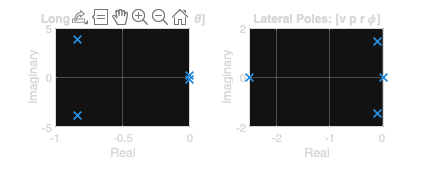


figure('Color', 'w', 'Position', [100 100 1100 440]);
tiledlayout(1,2);

nexttile;
plot(real(longPoles), imag(longPoles), 'x', 'LineWidth', 1.4, 'MarkerSize', 8);
grid on;
xlabel('Real');
ylabel('Imaginary');
title('Longitudinal Poles: [u w q \theta]');

nexttile;
plot(real(latPoles), imag(latPoles), 'x', 'LineWidth', 1.4, 'MarkerSize', 8);
grid on;
xlabel('Real');
ylabel('Imaginary');
title('Lateral Poles: [v p r \phi]');

## Part A: pure dampers

For the pure dampers, rate over control is the right transfer function.

Gq = data.transfer.q_over_delta_e;
Gp = data.transfer.p_over_delta_a;
Gr = data.transfer.r_over_delta_r;

pitch_damper_tf = minreal(zpk(Gq))


pitch_damper_tf =
 
           -2.9798 s (s+1.039) (s+0.03907)
  --------------------------------------------------
  (s^2 + 0.005821s + 0.03902) (s^2 + 1.673s + 15.55)
 
Continuous-time zero/pole/gain model.


roll_damper_tf = minreal(zpk(Gp))


roll_damper_tf =
 
  25.334 (s-0.006437) (s^2 + 0.1983s + 1.966)
  --------------------------------------------
  (s+2.527) (s-0.02904) (s^2 + 0.1843s + 2.14)
 
Continuous-time zero/pole/gain model.


yaw_damper_tf = minreal(zpk(Gr))


yaw_damper_tf =
 
  1.1396 (s+2.677) (s^2 - 0.009694s + 0.01663)
  --------------------------------------------
  (s+2.527) (s-0.02904) (s^2 + 0.1843s + 2.14)
 
Continuous-time zero/pole/gain model.


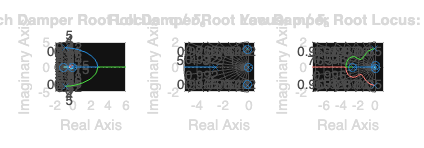


figure('Color', 'w', 'Position', [100 100 1200 420]);
tiledlayout(1,3);

nexttile;
rlocus(Gq);
grid on;
title('Pitch Damper Root Locus: q / \delta_e');

nexttile;
rlocus(Gp);
grid on;
title('Roll Damper Root Locus: p / \delta_a');

nexttile;
rlocus(Gr);
grid on;
title('Yaw Damper Root Locus: r / \delta_r');

## Pick pure damper gains

if ~exist('Kq_pick', 'var')
    Kq_pick = 0.4;
end
if ~exist('Kp_roll_pick', 'var')
    Kp_roll_pick = 0.2;
end

A_long_q = A_long - B_long(:, 3) * Kq_pick * [0 0 1 0];
A_lat_p = A_lat - B_lat(:, 1) * Kp_roll_pick * [0 1 0 0];

longQPoles = eig(A_long_q);
latPPoles = eig(A_lat_p);

damperGainSummary = table(Kq_pick, Kp_roll_pick)

damperGainSummary = 1×2 table
    Kq_pick    Kp_roll_pick
    _______    ____________

      0.4          0.2     


## Part B: add proportional outer-loop control

For the longitudinal path, I am using u as the small-disturbance airspeed state. For the lateral path, I am using phi for bank angle.

Gu = ss(A_long_q, B_long(:, 1), [1 0 0 0], 0);
Gphi = ss(A_lat_p, B_lat(:, 1), [0 0 0 1], 0);

airspeed_p_tf = minreal(zpk(Gu))


airspeed_p_tf =
 
    0.00055962 (s+0.04174) (s^2 + 0.6136s + 14.21)
  ---------------------------------------------------
  (s^2 + 0.006096s + 0.04252) (s^2 + 0.4813s + 14.27)
 
Continuous-time zero/pole/gain model.


bank_p_tf = minreal(zpk(Gphi))


bank_p_tf =
 
         25.383 (s^2 + 0.185s + 1.964)
  --------------------------------------------
  (s+7.554) (s-0.01442) (s^2 + 0.2092s + 2.03)
 
Continuous-time zero/pole/gain model.


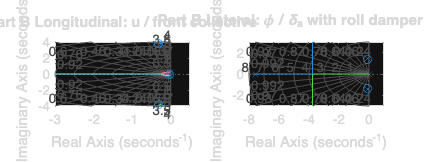


figure('Color', 'w', 'Position', [100 100 1100 420]);
tiledlayout(1,2);

nexttile;
rlocus(Gu);
grid on;
title('Part B Longitudinal: u / front collective');

nexttile;
rlocus(Gphi);
grid on;
title('Part B Lateral: \phi / \delta_a with roll damper locked');

## Pick one proportional airspeed gain

if ~exist('Kv_pick', 'var')
    Kv_pick = 0.15;
end

A_long_p = A_long_q - B_long(:, 1) * Kv_pick * [1 0 0 0];
longPPoles = eig(A_long_p);

longPPoleTable = table(real(longPPoles), imag(longPPoles), ...
    'VariableNames', {'real_part','imag_part'})

longPPoleTable = 4×2 table
    real_part     imag_part
    __________    _________

      -0.24064      3.7697 
      -0.24064     -3.7697 
    -0.0030898     0.20619 
    -0.0030898    -0.20619 


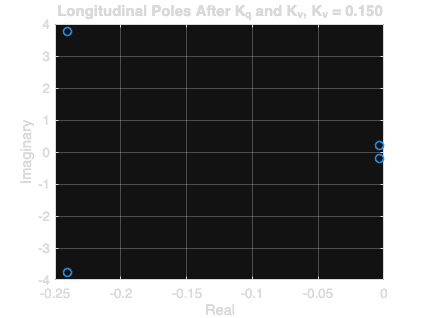


figure('Color', 'w', 'Position', [100 100 560 420]);
plot(real(longPPoles), imag(longPPoles), 'o', 'LineWidth', 1.2, 'MarkerSize', 6);
grid on;
xlabel('Real');
ylabel('Imaginary');
title(sprintf('Longitudinal Poles After K_q and K_v, K_v = %.3f', Kv_pick));

## Part C: add integral action

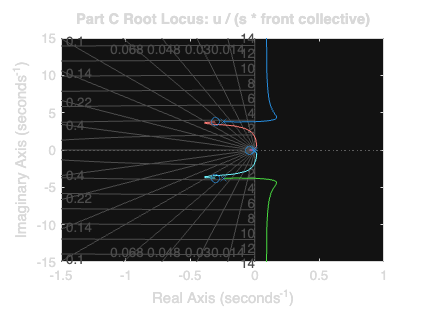

Gu_p = ss(A_long_p, B_long(:, 1), [1 0 0 0], 0);
Gi = minreal(Gu_p / tf('s'));

figure('Color', 'w', 'Position', [100 100 560 420]);
rlocus(Gi);
grid on;
title('Part C Root Locus: u / (s * front collective)');

## Pick one integral gain

if ~exist('Ki_pick', 'var')
    Ki_pick = 0.02;
end

A_long_pi = [A_long_p zeros(4,1); -[1 0 0 0] 0];
B_long_pi = [B_long(:,1); 0];
piPoles = eig(A_long_pi - B_long_pi * Ki_pick * [zeros(1,4) 1]);

piPoleTable = table(real(piPoles), imag(piPoles), ...
    'VariableNames', {'real_part','imag_part'})

piPoleTable = 5×2 table
    real_part     imag_part
    __________    _________

      -0.24064      3.7697 
      -0.24064     -3.7697 
    -0.0030952     0.20616 
    -0.0030952    -0.20616 
    1.0944e-05           0 


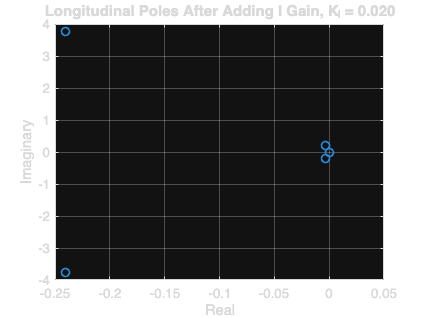


figure('Color', 'w', 'Position', [100 100 560 420]);
plot(real(piPoles), imag(piPoles), 'o', 'LineWidth', 1.2, 'MarkerSize', 6);
grid on;
xlabel('Real');
ylabel('Imaginary');
title(sprintf('Longitudinal Poles After Adding I Gain, K_i = %.3f', Ki_pick));

## Gain summary

gainSummary = table(Kq_pick, Kp_roll_pick, Kv_pick, Ki_pick)

gainSummary = 1×4 table
    Kq_pick    Kp_roll_pick    Kv_pick    Ki_pick
    _______    ____________    _______    _______

      0.4          0.2          0.15       0.02  
